# Reglertuning

This script evaluates the error of refrence position (from Trajectory) and actual observed position for various Controllerparameters.

clear all, close all, clc;

## Constants


%Kreisfahrt 103.3864ms  Sinusfahrt 160.3870ms   WallCrash 106ms --> Mean
%123.2578ms (61cycles) (cycle time: 2 ms)

## Set up the Import Options and import the data

% Import the data
data = readtable("tuning2_20.csv");


% Trim data
enableRobot = data.enableRobot;
yBoArrivedAtDestination = data.yBoArrivedAtDestination;
FIRST_SAMPLE_IDX = find(enableRobot, 1, "first")+2;  %+2 da sonst trajektorie noch nicht ref pos verfügbar
LAST_SAMPLE_IDX = find(yBoArrivedAtDestination, 1, "first");

data = data(FIRST_SAMPLE_IDX:LAST_SAMPLE_IDX,:);

% Convert to output type
t = data.Name / 1000;       % ms -> s
t = t - t(1);           % ensure t(0) = 0 s

% read pose data
xRef = data.xRef;
xKalman = data.xKalman;
yRef = data.yRef;
yKalman = data.yKalman;
thetaRef = data.thetaRef;
thetaKalman = data.thetaKalman;

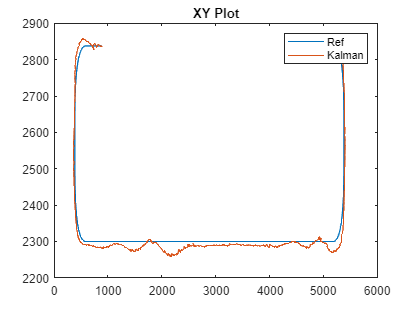

% plot XY
plot(xRef, yRef, xKalman, yKalman);
title("XY Plot");
legend("Ref", "Kalman");

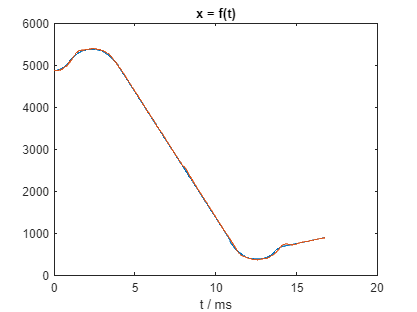


% plot x = f(t)
plot(t, xRef, t, xKalman);
title("x = f(t)");
xlabel("t / ms");

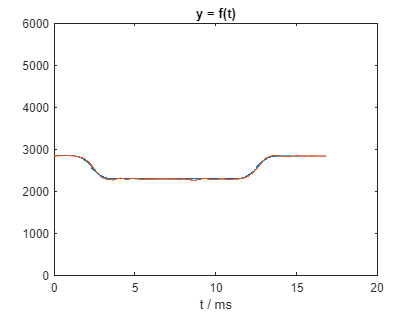



% plot y = f(t)
plot(t, yRef, t, yKalman);
title("y = f(t)");
xlabel("t / ms");
ylim([0, 6000]);

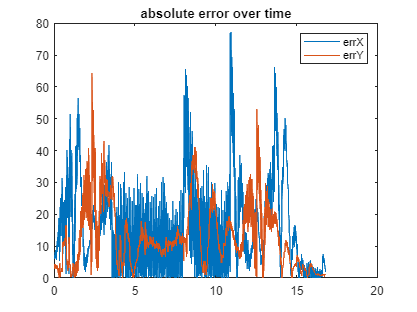



sseX = zeros(1,length(xRef));
for i = [1 : length(xRef)]
    % calculate absolute error in each axis 
    seX(i) = (xRef(i)-xKalman(i))^2;
    seY(i) = (yRef(i)-yKalman(i))^2;
    seTheta(i) = (thetaRef(i)-thetaKalman(i))^2;
    sseX(i) = sum(seX);
    sseY(i) = sum(seY);
    sseTheta(i) = sum(seTheta);
end

% plot results
plot(t, sqrt(seX), t, sqrt(seY));
title("absolute error over time");
legend("errX", "errY");



% plot(t, sseX);
% title("Sum of squared error over time in X");
% xlabel("time [s]")
% ylabel("SSE in X [mm^2]");


avgErrX = mean(sqrt(seX))

avgErrX = 15.4189

avgErrY = mean(sqrt(seY))

avgErrY = 12.7604

avgErrTheta = mean(sqrt(seTheta))

avgErrTheta = 0.0256


varX = sqrt(var(sqrt(seX)))

varX = 12.9787

varY = sqrt(var(sqrt(seY)))

varY = 9.8194

varTheta = sqrt(var(sqrt(seTheta)))

varTheta = 0.0283


gainX = data.controllerKX(1)

gainX = 4

gainY = data.controllerKY(1)

gainY = 4

gainTheta = data.controllerKTheta(1)

gainTheta = 0.5000
























% mrsX = sqrt(sseX(end))/length(sseX)           % error per sample in mm
% mrsY = sqrt(sseY(end))/length(sseY)
% mrsTheta = sqrt(sseTheta(end))/length(sseTheta)


